# 2. Making the room IIR

## 2.1 Bounce bounce...

### 2.1.1 FIR implementation 30ms


$$y(n) = x(n) + \alpha x(n-delay)$$



$$h(n) = \begin{cases}1 & \text{if} & n=0\\\alpha & \text{if} & n=delay\\ 0 &\text{else}\end{cases}$$



$$H(z) = \sum_{n=0}^\infty h(n)z^{-n} = z^0 + \alpha z^{-delay} = \frac{z^{delay} + \alpha}{z^{delay}}$$


alpha = 0.6; td = 30e-3;

The variable $delay$ measures the delay in samples. Choosing a sampling frequency of $f_s=44100\;\text{Hz}$ we can determine the number of samples equivalent to a delay of $30\;\text{ms}$.

fs = 44100;
delay = fs*td

delay = 1323

fir.b = 1; fir.b(delay+1) = alpha;
fir.a = 1; fir.a(delay+1) = 0;

### 2.1.2 IIR implementation 30ms


$$y(n) + \alpha y(n-delay) = x(n)$$



$$\sum_{n=0}^\infty \left[ y(n)+\alpha y(n-delay)\right] z^{-n} = \sum_{n=0}^\infty x(n) z^{-n} \Longleftrightarrow Y(z) + \alpha Y(z) z^{-delay} = X(z) \Longleftrightarrow Y(z)\left[ \frac{z^{delay} + \alpha}{z^{delay}} \right] = X(z) \Longleftrightarrow H(z) = \frac{z^{delay}}{z^{delay} + \alpha}$$


alpha = 0.6; td = 30e-3;

The variable $delay$ measures the delay in samples. Choosing a sampling frequency of $f_s=44100\;\text{Hz}$ we can determine the number of samples equivalent to a delay of $30\;\text{ms}$.

fs = 44100;
delay = fs*td

delay = 1323

iir.a = 1; iir.a(delay+1) = alpha;
iir.b = 1; iir.b(delay+1) = 0;

### 2.1.4 Spectra and impulse responses

f = 0:0.01:fs/2;
[fir.h,~] = freqz(fir.b,fir.a,f,fs);
[iir.h,~] = freqz(iir.b,iir.a,f,fs);

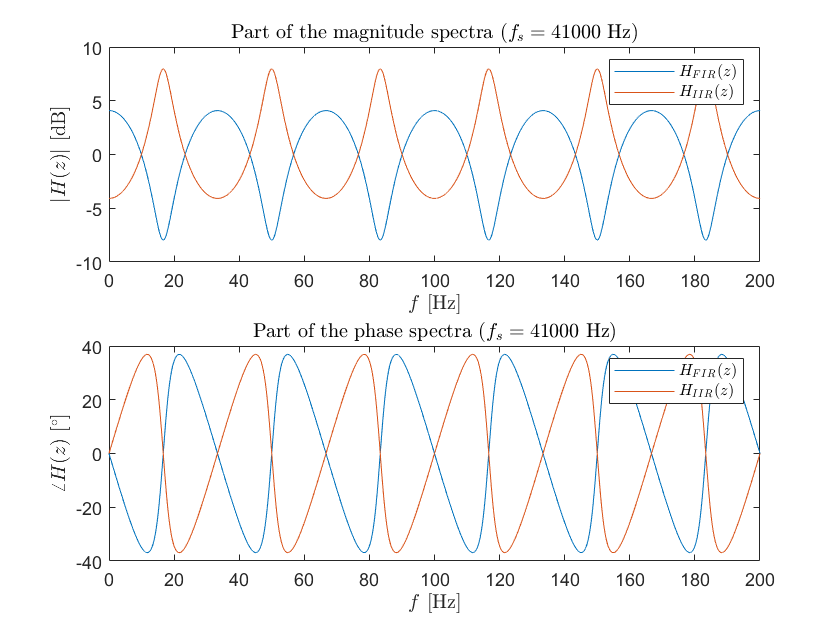

figure(12); 
subplot(2,1,1); plot(f,20*log10(abs(fir.h))); hold on; plot(f,20*log10(abs(iir.h))); hold off; xlim([0 200]); 
title("Part of the magnitude spectra ($f_s=41000$ Hz)",'Interpreter',"latex"); xlabel("$f$ [Hz]",'Interpreter','latex'); ylabel("$|H(z)|$ [dB]",'Interpreter','latex'); 
legend(["$H_{FIR}(z)$" "$H_{IIR}(z)$"],'Interpreter',"latex")
subplot(2,1,2); plot(f,angle(fir.h)*180/pi); hold on; plot(f,angle(iir.h)*180/pi); hold off; xlim([0 200]);
title("Part of the phase spectra ($f_s=41000$ Hz)",'Interpreter',"latex"); xlabel("$f$ [Hz]",'Interpreter','latex');  ylabel("$\angle H(z)$ [$^\circ$]",'Interpreter','latex')
legend(["$H_{FIR}(z)$" "$H_{IIR}(z)$"],'Interpreter',"latex")
saveas(gcf,'plots/bounce_spectra.png')

[fir.imp,fir.t] = impz(fir.b,fir.a, 2000, fs);
[iir.imp,iir.t] = impz(iir.b,iir.a, 20000, fs);

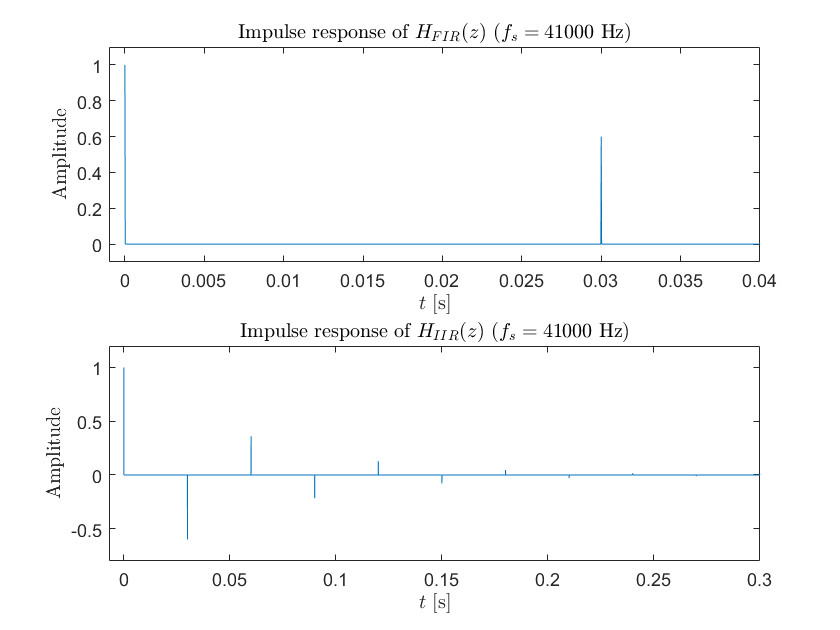

figure(13); 
subplot(2,1,1); plot(fir.t,fir.imp); xlim([-0.001 0.04]); ylim([-0.1 1.1])
title("Impulse response of $H_{FIR}(z)$ ($f_s=41000$ Hz)",'Interpreter',"latex"); xlabel("$t$ [s]",'Interpreter',"latex"); ylabel("Amplitude",'Interpreter',"latex")
subplot(2,1,2); plot(iir.t,iir.imp); xlim([-0.007 0.3]); ylim([-0.8 1.2])
title("Impulse response of $H_{IIR}(z)$ ($f_s=41000$ Hz)",'Interpreter',"latex"); xlabel("$t$ [s]",'Interpreter',"latex"); ylabel("Amplitude",'Interpreter',"latex")
saveas(gcf,'plots/bonuce_impulse.png')

### 2.1.5 Other delays (10ms and 200ms)

alpha = 0.6; td1 = 10e-3; td2 = 200e-3;
fs = 44100;
delay1 = fs*td1

delay1 = 441

fir10.b = 1; fir10.b(delay1+1) = alpha;
fir10.a = 1; fir10.a(delay1+1) = 0;
iir10.a = 1; iir10.a(delay1+1) = alpha;
iir10.b = 1; iir10.b(delay1+1) = 0;
delay2 = fs*td2

delay2 = 8820

fir200.b = 1; fir200.b(delay2+1) = alpha;
fir200.a = 1; fir200.a(delay2+1) = 0;
iir200.a = 1; iir200.a(delay2+1) = alpha;
iir200.b = 1; iir200.b(delay2+1) = 0;

f = 0:0.01:fs/2;
[fir10.h,~] = freqz(fir10.b,fir10.a,f,fs);
[iir10.h,~] = freqz(iir10.b,iir10.a,f,fs);
[fir200.h,~] = freqz(fir200.b,fir200.a,f,fs);
[iir200.h,~] = freqz(iir200.b,iir200.a,f,fs);

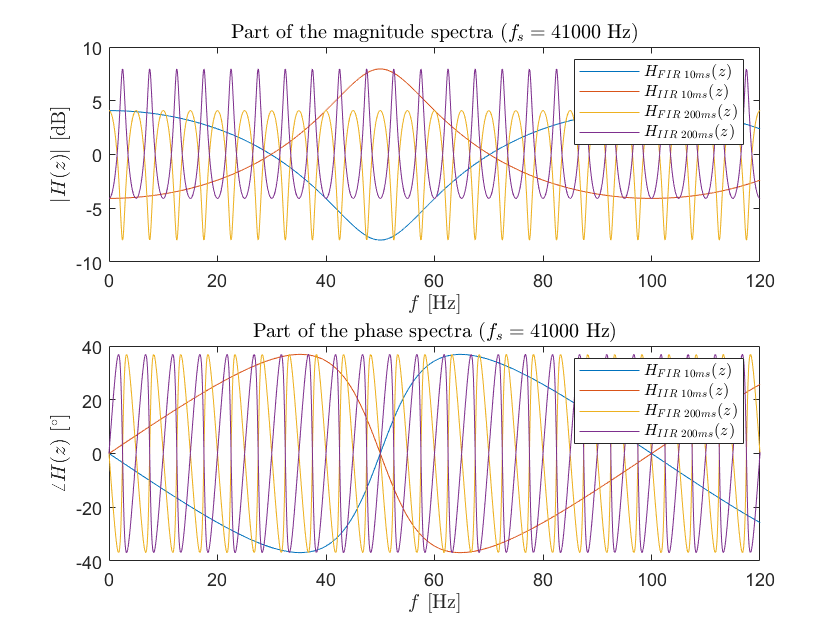

figure(22); 
subplot(2,1,1); plot(f,20*log10(abs(fir10.h))); hold on; plot(f,20*log10(abs(iir10.h))); plot(f,20*log10(abs(fir200.h))); plot(f,20*log10(abs(iir200.h))); hold off; xlim([0 120]); 
title("Part of the magnitude spectra ($f_s=41000$ Hz)",'Interpreter',"latex"); xlabel("$f$ [Hz]",'Interpreter','latex'); ylabel("$|H(z)|$ [dB]",'Interpreter','latex'); 
legend(["$H_{FIR\;10ms}(z)$" "$H_{IIR\;10ms}(z)$" "$H_{FIR\;200ms}(z)$" "$H_{IIR\;200ms}(z)$"],'Interpreter',"latex")
subplot(2,1,2); plot(f,angle(fir10.h)*180/pi); hold on; plot(f,angle(iir10.h)*180/pi); plot(f,angle(fir200.h)*180/pi); plot(f,angle(iir200.h)*180/pi); hold off; xlim([0 120]);
title("Part of the phase spectra ($f_s=41000$ Hz)",'Interpreter',"latex"); xlabel("$f$ [Hz]",'Interpreter','latex');  ylabel("$\angle H(z)$ [$^\circ$]",'Interpreter','latex')
legend(["$H_{FIR\;10ms}(z)$" "$H_{IIR\;10ms}(z)$" "$H_{FIR\;200ms}(z)$" "$H_{IIR\;200ms}(z)$"],'Interpreter',"latex")

[fir10.imp,fir10.t] = impz(fir10.b,fir10.a, 2000, fs);
[iir10.imp,iir10.t] = impz(iir10.b,iir10.a, 20000, fs);
[fir200.imp,fir200.t] = impz(fir200.b,fir200.a, 200000, fs);
[iir200.imp,iir200.t] = impz(iir200.b,iir200.a, 200000, fs);

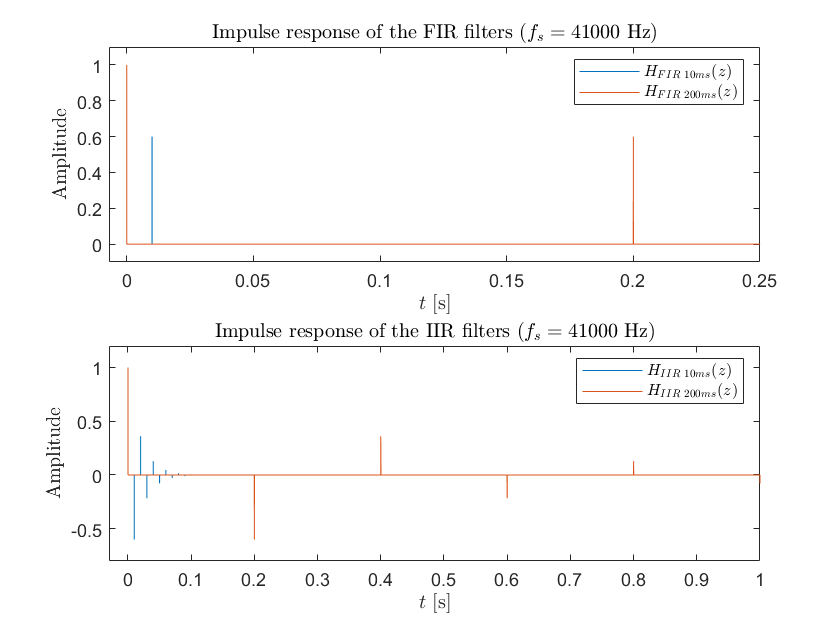

figure(23); 
subplot(2,1,1); plot(fir10.t,fir10.imp);hold on; plot(fir200.t,fir200.imp); hold off; xlim([-0.007 0.25]); ylim([-0.1 1.1])
title("Impulse response of the FIR filters ($f_s=41000$ Hz)",'Interpreter',"latex"); xlabel("$t$ [s]",'Interpreter',"latex"); ylabel("Amplitude",'Interpreter',"latex")
legend(["$H_{FIR\;10ms}(z)$" "$H_{FIR\;200ms}(z)$"],'Interpreter',"latex")
subplot(2,1,2); plot(iir10.t,iir10.imp); hold on; plot(iir200.t,iir200.imp); hold off; xlim([-0.03 1]); ylim([-0.8 1.2])
title("Impulse response of the IIR filters ($f_s=41000$ Hz)",'Interpreter',"latex"); xlabel("$t$ [s]",'Interpreter',"latex"); ylabel("Amplitude",'Interpreter',"latex")
legend(["$H_{IIR\;10ms}(z)$" "$H_{IIR\;200ms}(z)$"],'Interpreter',"latex")
saveas(gcf,'plots/bonuce_impulse.png')

### 2.1.4 Signals

[signal,~] = audioread("sounds/scrambled_eggs_5s.wav");
t = 0:1/fs:(length(signal)/fs-1/fs);

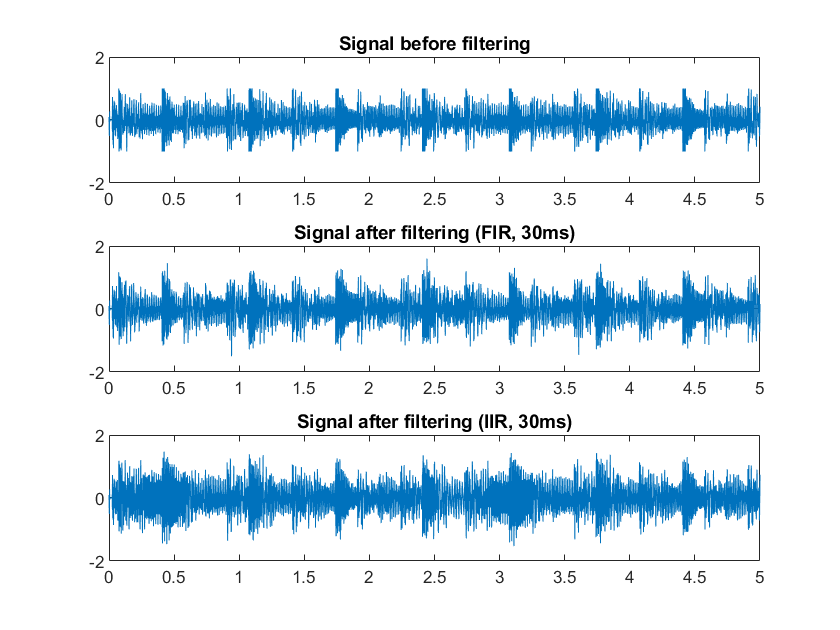

figure(30);
subplot(3,1,1); plot(t,signal); ylim([-2 2]); title("Signal before filtering");
subplot(3,1,2); plot(t,filter(fir.b,fir.a,signal)); ylim([-2 2]); title("Signal after filtering (FIR, 30ms)");
subplot(3,1,3); plot(t,filter(iir.b,iir.a,signal)); ylim([-2 2]); title("Signal after filtering (IIR, 30ms)");

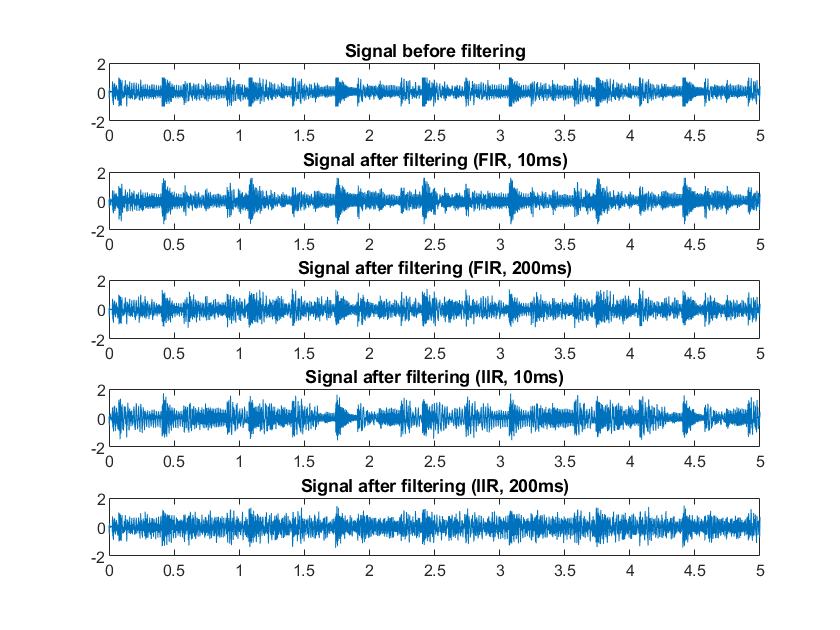

figure(31);
subplot(5,1,1); plot(t,signal); ylim([-2 2]); title("Signal before filtering")
subplot(5,1,2); plot(t,filter(fir10.b,fir10.a,signal)); ylim([-2 2]); title("Signal after filtering (FIR, 10ms)");
subplot(5,1,3); plot(t,filter(fir200.b,fir200.a,signal)); ylim([-2 2]); title("Signal after filtering (FIR, 200ms)");
subplot(5,1,4); plot(t,filter(iir10.b,iir10.a,signal)); ylim([-2 2]); title("Signal after filtering (IIR, 10ms)");
subplot(5,1,5); plot(t,filter(iir200.b,iir200.a,signal)); ylim([-2 2]); title("Signal after filtering (IIR, 200ms)");
saveas(gcf,'plots/bounce_signals.png')

### 2.1.5 Listening

sound(filter(fir10.b,fir10.a,signal),fs) % FIR with 10ms delay

sound(filter(iir10.b,iir10.a,signal),fs) % IIR with 10ms delay

sound(filter(fir.b,fir.a,signal),fs) % FIR with 30ms delay

sound(filter(iir.b,iir.a,signal),fs) % IIR with 30ms delay

sound(filter(fir200.b,fir200.a,signal),fs) % FIR with 200ms delay

sound(filter(iir200.b,iir200.a,signal),fs) % IIR with 200ms delay